## **Objective**

The purpose of this activity is to generate a smooth path between two points with specific orientations, utilizing a clothoid curve based on Fresnel integrals. The path is designed to smoothly transition from an initial position and orientation to a final position and orientation with varying curvature, making it suitable for applications in robotics and autonomous navigation.

## Definition

A **clothoid**, also known as a **Cornu spiral** or **Euler spiral**, is a type of curve whose curvature changes linearly with its arc length. Clothoids are particularly important in engineering applications such as road and railway design, where a gradual transition between a straight path and a curve is needed to ensure comfort and safety.

**Key Characteristics of Clothoids**

**Linearly Varying Curvature**:

- The curvature κ(s)\kappa(s)κ(s) of a clothoid is directly proportional to the arc length sss: κ(s)=a⋅s where **a** is a constant that determines how quickly the curvature changes.

**Properties**:

- As s increases, the clothoid starts as a nearly straight line and gradually spirals outward.

- It is symmetric around the origin, with the shape determined by how κ(s) varies with s.

**Cornu Spiral**:

- A specific type of clothoid known as the **Cornu spiral** is often used in optics to describe diffraction patterns. The curve represented by the Fresnel cosine and sine integrals, forms the shape of a Cornu spiral.

**Applications of Clothoids**

**Road and Railway Design**:

- Clothoids are used to design transition curves between straight paths and circular arcs, ensuring a smooth change in curvature. This gradual change reduces sudden lateral acceleration, improving comfort for passengers and safety for vehicles.

**Optics**:

- In wave optics, the Cornu spiral is used to represent diffraction and interference patterns, particularly in analyzing the behavior of light as it passes through slits and apertures.

**Robotics and Path Planning**:

- Clothoids are used in the algorithms for path planning where robots or autonomous vehicles need smooth trajectories that change direction gradually.

**Benefits of Using Clothoids**

- **Smooth Transitions**: They provide a continuous and smooth change in curvature, preventing sudden changes that can be uncomfortable or unsafe.

- **Predictability**: The linear change in curvature makes clothoids easy to model and predict computationally.

- **Efficiency in Design**: Engineers use clothoids in CAD software to design roadways, railways, and roller coasters efficiently, balancing curvature and safety.

**Example Use Case: Road Design**

In road design, the path may need to transition from a straight section (zero curvature) to a circular curve (constant curvature). A clothoid segment is used in between to ensure that drivers experience a gradual change in steering angle:

- The curvature starts at zero (straight path) and gradually increases to match that of the circular curve.

- This design minimizes the risk of skidding and enhances the comfort of driving.

Clothoids are an essential concept in fields requiring smooth changes in curvature, ensuring both practical and theoretical benefits in various engineering and physics applications.

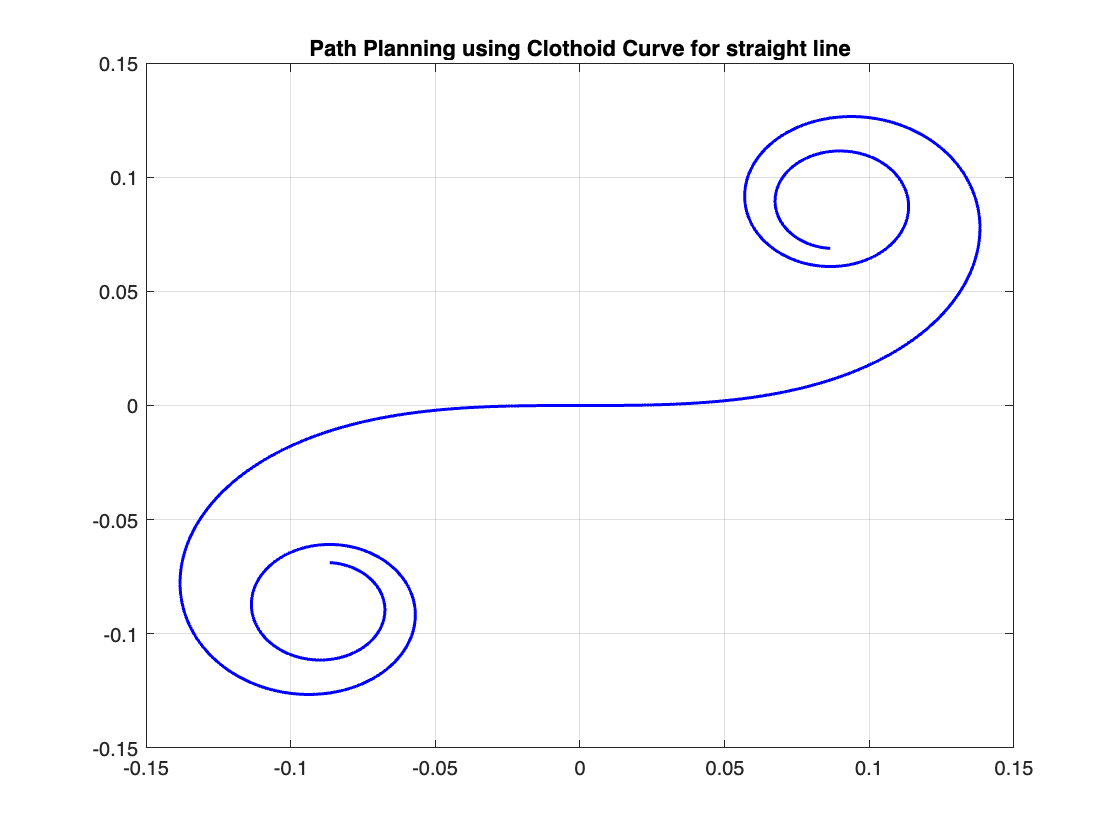

% Path Planning Using Fresnel Integrals
% Definitions for initial and final positions and orientations


syms s % th - angle value

% coefficient of clothoid curve
a = 100;

% Define curvature for a line
kappa_l = a*s; % for a straight line)

% Compute theta(s), x(s), and y(s) using Fresnel integrals
theta_s = int(kappa_l); % Integral of curvature to get theta(s)
x_s = int(cos(theta_s)); % x(s) position by integrating cos(theta)
y_s = int(sin(theta_s)); % y(s) position by integrating sin(theta)

% % Transform to the initial position and orientation
% x_global = x_s*cos(theta_i) - y_s * sin(theta_i) + xi;
% y_global = x_s* sin(theta_i) + y_s * cos(theta_i) + yi;

% Plot Results
s = -0.5:0.001:0.5;
x_s = eval(x_s);
y_s = eval(y_s);
figure;
plot(x_s, y_s, 'b', 'LineWidth', 1.5); hold on;
title('Path Planning using Clothoid Curve for straight line');
grid on;

% for arc of a circle k = r*th
syms th
r = 100;
kappa_arc = r*th % arc of a circle

$$kappa\_arc = 100\,\mathrm{th}$$

theta_s = int(kappa_arc) % Integral of curvature to get theta(s)

$$theta\_s = 50\,{\mathrm{th}}^{2}$$

x_s = int(cos(theta_s)) % x(s) position by integrating cos(theta)

$$x\_s = \frac{\sqrt{\pi }\,C\left(\frac{10\,\mathrm{th}}{\sqrt{\pi }}\right)}{10}$$

y_s = int(sin(theta_s)) % y(s) position by integrating sin(theta)

$$y\_s = \frac{\sqrt{\pi }\,S\left(\frac{10\,\mathrm{th}}{\sqrt{\pi }}\right)}{10}$$

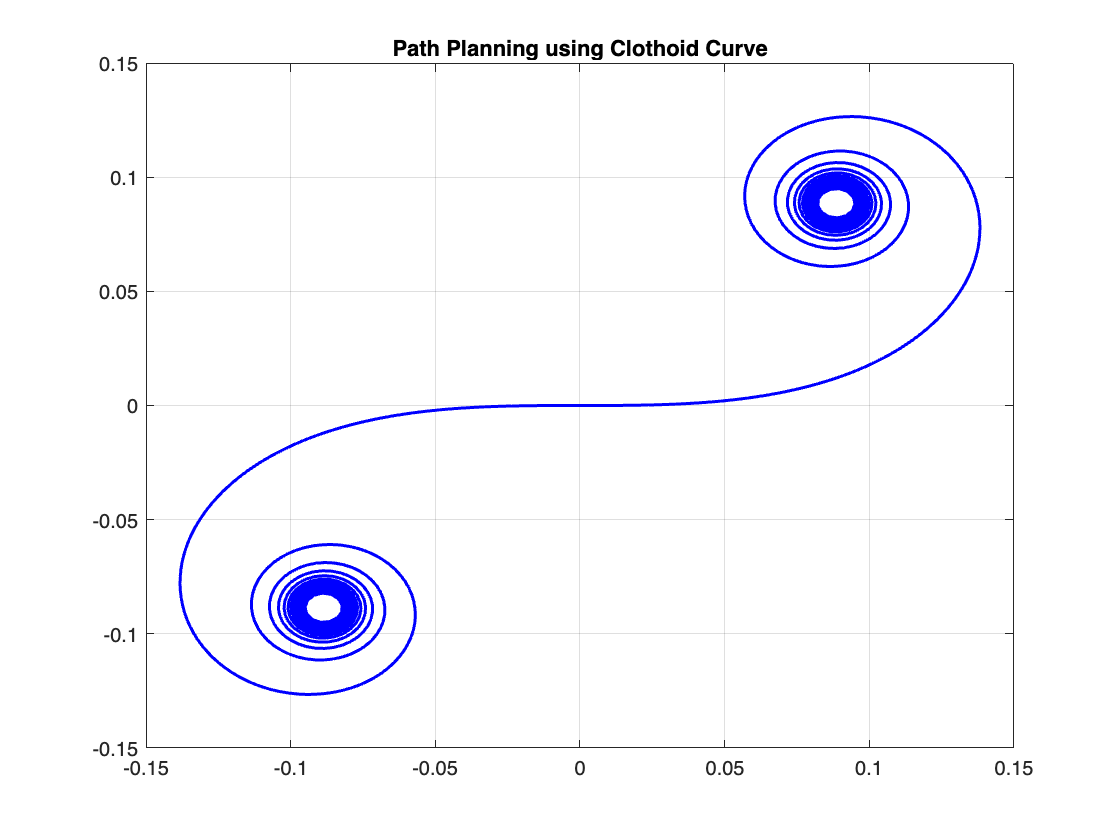

% Plot Results
th = linspace(-pi/2, pi/2, 1000); % Linearly spaced arc angle
x_s = eval(x_s);
y_s = eval(y_s);
figure;
plot(x_s, y_s, 'b', 'LineWidth', 1.5); hold on;
title('Path Planning using Clothoid Curve');
grid on;

% for clothoid k = a*s^2
% syms s
% a = 1;
% kappa_c = a*s^2; % clothoid
% theta_s = int(kappa_c, s) % Integral of curvature to get theta(s)
% x_s = int(cos(theta_s)) % x(s) position by integrating cos(theta)
% y_s = int(sin(theta_s)) % y(s) position by integrating sin(theta)
% 
% %Plot Results
% s1 = -0.5:0.01:0.5;
% x_s = eval(subs(x_s, s1));
% y_s = eval(subs(y_s, s, s1));
% 
% figure;
% plot(x_s, y_s, 'b', 'LineWidth', 1.5); hold on;
% title('Path Planning using Clothoid Curve');
% grid on;


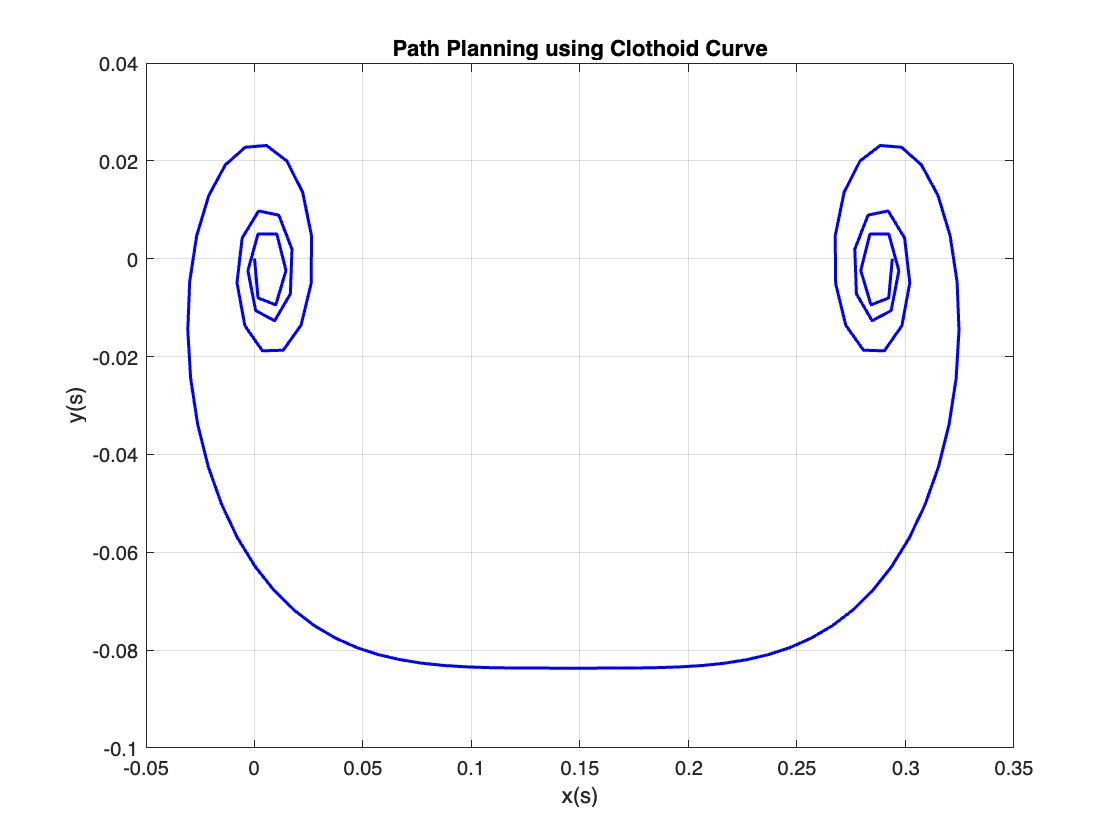

syms s
a = 500;
kappa_c = a * s^2; % Clothoid curvature
theta_s = int(kappa_c, s); % Definite integral of curvature

% Numerical integration for x(s) and y(s)
s_vals = -0.5:0.01:0.5;
theta_vals = double(subs(theta_s, s, s_vals)); % Evaluate theta(s) for s_vals

x_s = cumtrapz(s_vals, cos(theta_vals)); % Numerical integration of cos(theta)
y_s = cumtrapz(s_vals, sin(theta_vals)); % Numerical integration of sin(theta)

% Plot results
figure;
plot(x_s, y_s, 'b', 'LineWidth', 1.5); hold on;
title('Path Planning using Clothoid Curve');
xlabel('x(s)');
ylabel('y(s)');
grid on;

xi = 0; yi = 0; theta_i = 0; % Initial position and orientation
xf = 10; yf = 10; theta_f = pi/4; % Final position and orientation

% Distance Calculation
d = sqrt((xf - xi)^2 + (yf - yi)^2);

% Deflection Calculation
alpha = theta_f - theta_i;

% Orientation from initial to final point
beta = alpha*atan2(yf - yi, xf - xi);


**Implications of the Coefficient ****a**:

- In this example, the coefficient a was set to 1. Adjusting a changes how rapidly the curvature increases with s. A higher value of a would result in a faster increase in curvature, making the curve tighter and more curved as sss deviates from zero.

**Potential Enhancements**:

- The plot could be enhanced by overlaying markers to indicate the start and end points or by showing the direction of movement along the path.

- Additional plots of κ(s) and θ(s) versus s could provide further insights into how the curvature and orientation evolve along the curve.

**Conclusion**

The plot effectively illustrates the gradual change in curvature that is a hallmark of clothoid paths. This characteristic makes clothoids ideal for applications requiring smooth transitions, such as roadways, railways, and autonomous vehicle paths. The mathematical derivation and resulting smooth curve validate the use of symbolic integration in MATLAB for path planning and design purposes.